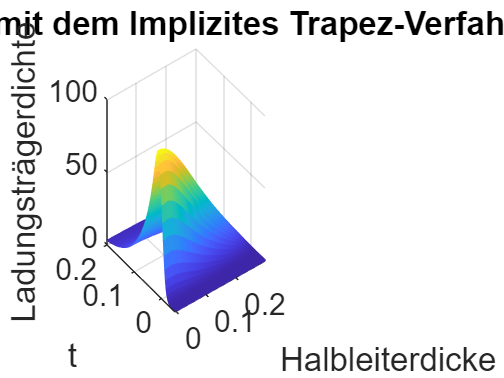

s_0 =10^4;
t_span = [-0.05,0.2];
tol = 10^-6;
N_max = 10;
N_ort = 100;
N_Zeit = 100;
c = konstanten;


%func = @(t,z) s_0.*exp(-(t.^2)./(2*0.01^2)).*exp(-c.a*z);

func = @(t,z) s_0*exp(-(t^2)/(2*0.01^2))*exp(-c.a*z);
z = (0:N_ort)'/N_ort * c.d;
func_simu = @(t,u) fd_nonlin(u,N_ort) + func(t,z);
d_func_simu = @(t,u) fd_nonlin_jac(u,N_ort);
y_a = zeros(N_ort+1,1);

[Trapez_T,Trapez_Y]=impl_trapez(@fd_4 ,t_span ,y_a ,N_Zeit ,@fd_4_jac ,tol ,N_max);

mesh(z,Trapez_T,Trapez_Y);

% mesh(X,Y,Z) erstellt eine Mesh-Darstellung
% d.h. eine dreidimensionale Fläche mit einfarbigen
% Kantenfarben und ohne Flächenfarben.

title('Simulation mit dem Implizites Trapez-Verfahren')
xlabel('Halbleiterdicke in z')
ylabel('t')
zlabel('Ladungsträgerdichte')
set(gca,'FontSize',25)
grid on

figure